# Linear Quadratic Control of a 3DOF Variable Speed Control Moment Gyroscope

%% initialising symbols for derivation of equations of motion
clear
syms psi_t(t) theta_t(t) phi_t(t) psi theta phi psi_dot theta_dot phi_dot ...
    psi_dot_dot theta_dot_dot phi_dot_dot I I0 tau1 tau2 tau3 q_j

### Defining Coordinate System and Frames of Reference

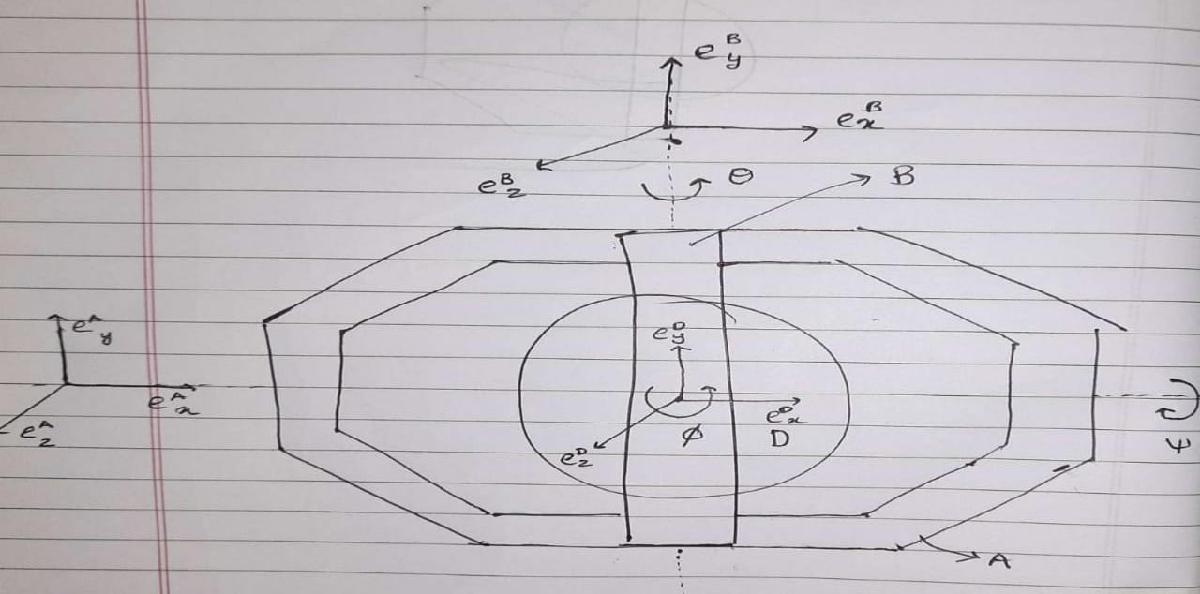

*Diagram of CMG with coordinate axes*

The frames of reference are defined as: 

D - body fixed reference frame of the disk (rotates with the disk) 

B - reference frame fixed to the inner (blue) gimbal 

A - reference frame fixed to the outer (red) gimbal 

Right orientated sets of orthogonal unit vectors $e_i^j$ with i = x, y, z and j = A, B, D, N are fixed to the natural (i.e., world) reference frame j = N and the bodies (A, B, and D) respectively. The origins of the coordinate frames are located in the centre of the disk (D).

The positive rotation direction of each frame is defined as:

$\psi$ - angle of rotation around the $e_x^A$-axis w.r.t. frame N

$\theta$ - angle of rotation around the $e_y^B$-axis w.r.t. frame A

$\phi$ - angle of rotation around the $e_z^D$-axis w.r.t. frame B

### Defining Rotation Matrices

We have the Cartesian Rotation Matrices given as: 


$$R_X \left(q_j \right)=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \cos \left(q_j \right) & -\sin \left(q_j \right)\\
0 & \sin \left(q_j \right) & \cos \left(q_j \right)
\end{array}\right\rbrack$$



$$R_Y \left(q_j \right)=\left\lbrack \begin{array}{ccc}
\cos \left(q_j \right) & 0 & \sin \left(q_j \right)\\
0 & 1 & 0\\
-\sin \left(q_j \right) & 0 & \cos \left(q_j \right)
\end{array}\right\rbrack$$



$$R_Z \left(q_j \right)=\left\lbrack \begin{array}{ccc}
\cos \left(q_j \right) & -\sin \left(q_j \right) & 0\\
\sin \left(q_j \right) & \cos \left(q_j \right) & 0\\
0 & 0 & 1
\end{array}\right\rbrack$$


R_X(q_j) = [1,0,0;0,cos(q_j),-sin(q_j);0,sin(q_j),cos(q_j)];
R_Y(q_j) = [cos(q_j),0,sin(q_j);0,1,0;-sin(q_j),0,cos(q_j)];
R_Z(q_j) = [cos(q_j),-sin(q_j),0;sin(q_j),cos(q_j),0;0,0,1];


We define the rotation matrices between the frames as: 


$$\begin{array}{l}
R_A^N =R_X \left(\psi \right)\\
R_B^A =R_Y \left(\theta \right)\\
R_D^B =R_Z \left(\phi \right)
\end{array}$$


R_NA = R_X(psi_t);
R_AB = R_Y(theta_t);
R_BD = R_Z(phi_t);


Utilizing these rotation matrices, we can describe the frame rotation between the reference frames as:

Rotation between reference frame N and the inner gimbal frame B as:


$$R_B^N =R_A^N \;$$

$$R_B^A$$


Rotation between reference frame N and the disk frame D as:


$$R_D^N =R_A^N \;$$

$$R_B^{A\;} {\;R}_D^B$$


R_NB = R_NA*R_AB;
R_ND = R_NB*R_BD;

### Net External Trorque Acting on the System

The external torque applied on the system is the torque applied by the motors used to actuate each gimbal 

Let us represent each motor torque as follows: 

$\tau_1$ - Torque applied to the outer gimbal (red) in the frame N 

$\tau_2$ - Torque applied to the inner gimbal (blue) in the frame A 

$\tau_3$ - Torque applied to vary the velocity of the disk (D) in the frame B

The net external torque on the system expressed in vector form in the N frame is therefore given as:


$$\overrightarrow{M_{\textrm{net}} } =\left\lbrack \begin{array}{c}
\tau_1 \\
0\\
0
\end{array}\right\rbrack +R_A^N \left\lbrack \begin{array}{c}
0\\
\tau_2 \\
0
\end{array}\right\rbrack +R_{B\;}^N \left\lbrack \begin{array}{c}
0\\
0\\
\tau_3 
\end{array}\right\rbrack$$


M_net = [tau1;0;0] + R_NA*[0;tau2;0] + R_NB*[0;0;tau3];

### Conservation of Angular Momentum Equation

We make the assumption that all the gimbals are massless. Therefore the moment of inertia contribution is only from the disk. Assuming symmetry of the disk, we can say: 


$$I_{\textrm{xx}} =I_{\textrm{yy}} =I$$



$$I_{\textrm{zz}\;} =I_0$$


Therefore the inertia matrix of the disk with respect to the D frame can be given as: 


$$I_D^D \;=\left\lbrack \begin{array}{ccc}
I & 0 & 0\\
0 & I & 0\\
0 & 0 & I_0 
\end{array}\right\rbrack$$


I_DD = diag([I,I,I0]);

To obtain the net angular momentum in the N frame we have to convert the intertia matrix to the N frame and express the angular velocities in the N frame. 

The inertia matrix expressed in the interial frame is given by: 


$$I_D^N \;=R_D^N \;I_D^D \;{R_D^N }^T$$


The net angular velocity of the system expressed in the intertial frame can be expressed as: 


$$\left\lbrack \begin{array}{c}
\dot{\psi} \\
0\\
0
\end{array}\right\rbrack +R_A^N \left\lbrack \begin{array}{c}
0\\
\dot{\theta} \\
0
\end{array}\right\rbrack +R_{B\;}^N \left\lbrack \begin{array}{c}
0\\
0\\
\dot{\phi} 
\end{array}\right\rbrack$$


Therefore we can write the net angular momentum as: 


$$\overrightarrow{H_{\textrm{net}} } =\;$$

$$R_D^N \;I_D^D \;{R_D^N }^T \;\left(\left\lbrack \begin{array}{c}
\dot{\psi} \\
0\\
0
\end{array}\right\rbrack +R_A^N \left\lbrack \begin{array}{c}
0\\
\dot{\theta} \\
0
\end{array}\right\rbrack +R_{B\;}^N \left\lbrack \begin{array}{c}
0\\
0\\
\dot{\phi} 
\end{array}\right\rbrack \right)$$


Therefore we can write the conservation of angular momentum equation as: 


$$\overrightarrow{M_{\textrm{net}} |_N } \;=\frac{d}{\textrm{dt}}\left(\overrightarrow{H_{\textrm{net}} } |_N \right)$$


H_net = R_ND*I_DD*R_ND.'*([diff(psi_t,t);0;0] + R_NA*[0;diff(theta_t,t);0] + R_NB*[0;0;diff(phi_t,t)]);

% differentiating angular momentum with respect to time
H_net_dot = diff(H_net,t);

% making substitution of double time derivative with symbolic double dot
% for convenience for finding jacoboians
ang_accel_t = [diff(psi_t,t,t);diff(theta_t,t,t);diff(phi_t,t,t)];
ang_accel = [psi_dot_dot;theta_dot_dot;phi_dot_dot];

% making substitution of double time derivative with symbolic dot
% for convenience for finding jacoboians
ang_vel_t = [diff(psi_t,t);diff(theta_t,t);diff(phi_t,t)];
ang_vel = [psi_dot;theta_dot;phi_dot];

% making substitution of angles from functions of time to variables
% for convenience for finding jacoboians
ang_t = [psi_t;theta_t;phi_t];
ang = [psi;theta;phi];

H_net_dot = subs(H_net_dot,[ang_accel_t;ang_vel_t;ang_t],[ang_accel;ang_vel;ang]);

%% expressing the system in dx/dt = f(x,u) form 
temp = jacobian(H_net_dot,ang_accel);

temp_inv = inv(temp);

rem = subs(H_net_dot,ang_accel,[0;0;0]);

ang_dot_dot = temp_inv*(M_net-rem);

state_dot = [ang_dot_dot;psi_dot;theta_dot;phi_dot];

state_dot = subs(state_dot,[ang_accel_t;ang_vel_t;ang_t],[ang_accel;ang_vel;ang]);

### Obtaining Linear Form 

We express the system of equations derived from the equation of motion in the form: 


$$\dot{x} \;=f\left(x,u\right)$$


Here, $x\;=\left\lbrack \begin{array}{c}
\dot{\psi} \\
\dot{\theta} \\
\dot{\phi} \\
\psi \\
\theta \\
\phi 
\end{array}\right\rbrack$

And, $u\;=\left\lbrack \begin{array}{c}
\tau_1 \\
\tau_2 \\
\tau_3 
\end{array}\right\rbrack$

state = [psi_dot;theta_dot;phi_dot;psi;theta;phi];
input = [tau1;tau2;tau3];

We obtain the linear expression for the system by taking the jacobian of $f\left(x,u\right)$ with respect to $x$ and $u$ to obtain the $A$ and $B$ matrices respectively for the form $\dot{x} \;=\textrm{Ax}+\textrm{Bu}$

B_sym = jacobian(state_dot,input);
A_sym = jacobian(state_dot,state);

## Simulating for various equilibrium states

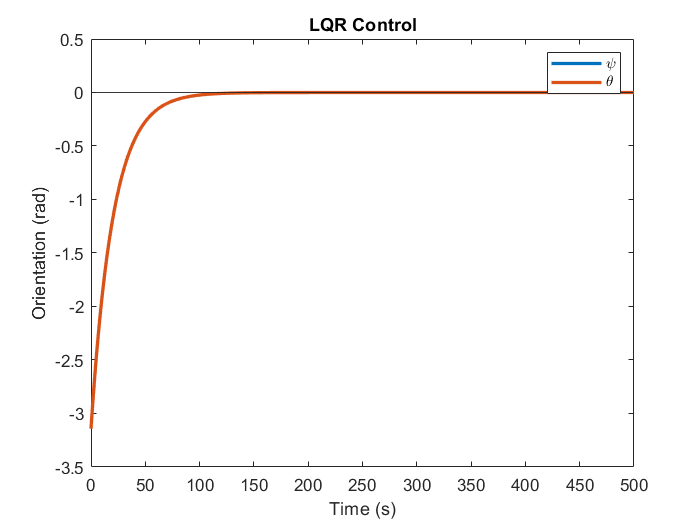

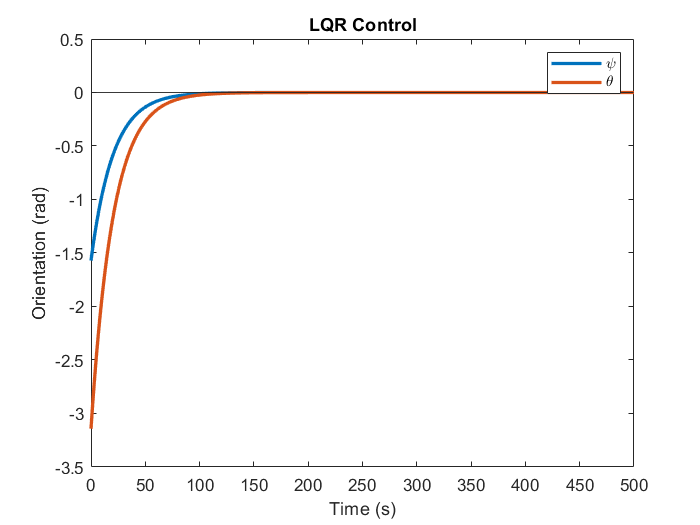

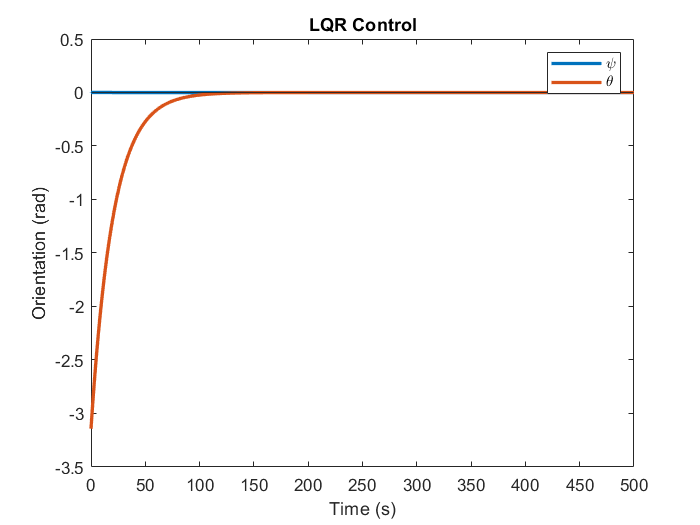

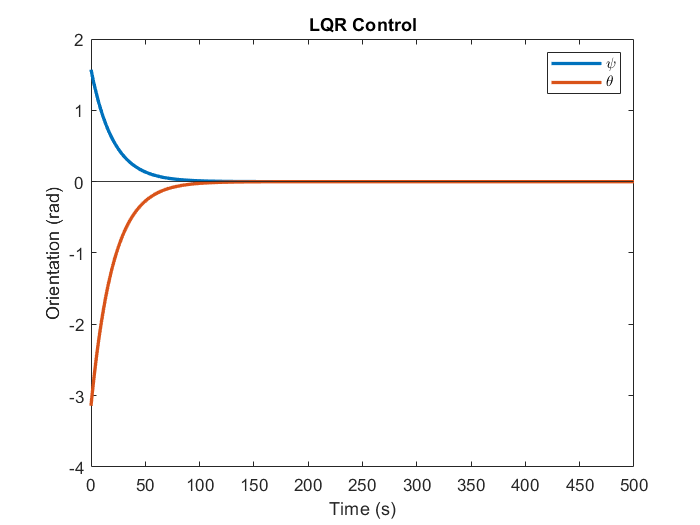

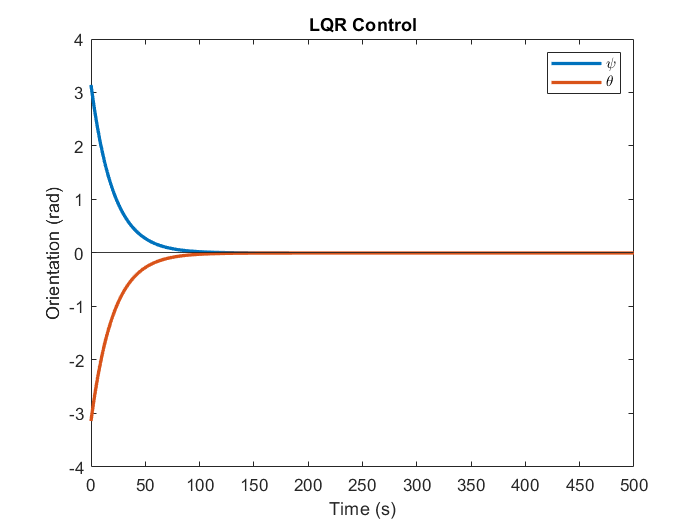

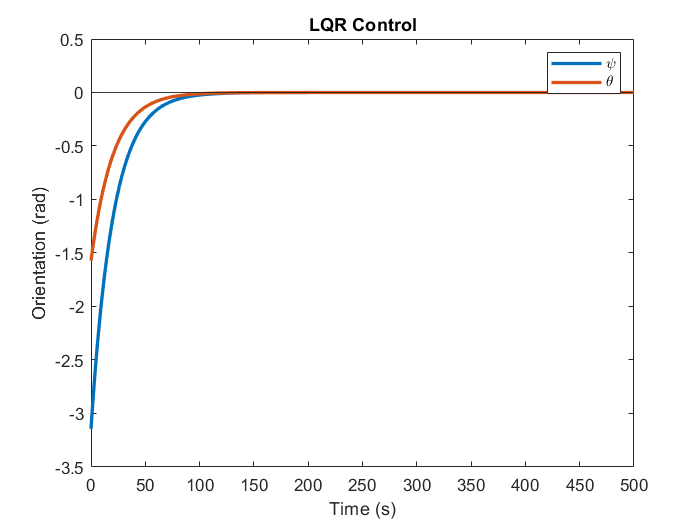

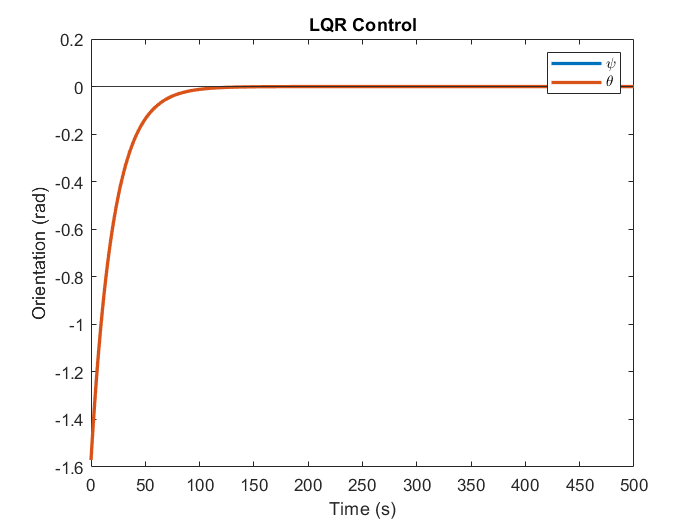

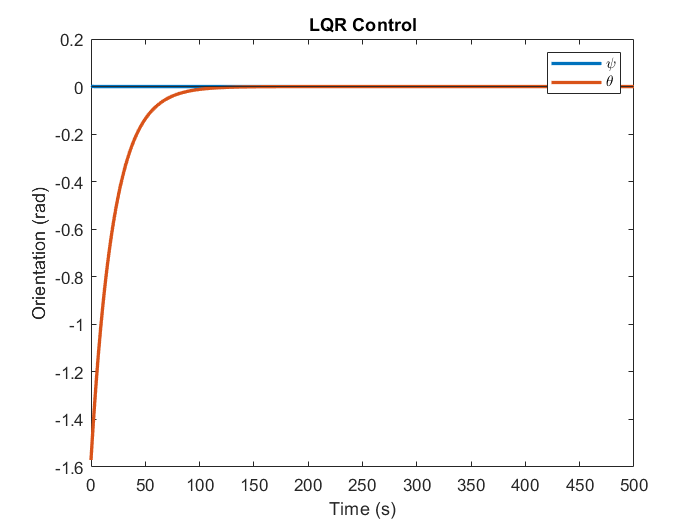

% specifiying equilibrium state of system
state_e = [0;0;100;0;0;0]; %
input_e = [0;0;0];

A = subs(A_sym,[state;input],[state_e;input_e]);
B = subs(B_sym,[state;input],[state_e;input_e]);

% defining the control matrices Q and R to compute the LQR gain
Q=diag([10,10,10,0.10,0.10,0.10]);
R=100*eye(3);
% substituting values of moments of inertia in A and B and converting to
% double 
A_fun=formula(A);
B_fun=formula(B);
B_LQR=subs(B_fun,{I,I0},{0.00284584,0.00563843});
A_LQR=subs(A_fun,{I,I0},{0.00284584,0.00563843});
A_LQR=double(A_LQR);
B_LQR=double(B_LQR);
% checking controllability of the system
C = ctrb(A_LQR,B_LQR);

i_max = 2;
for i = -i_max:1:i_max
    j_max = 2;
    for j = -j_max:1:j_max
        if rank(C) == length(A_LQR) 
            %disp('The system is controllable for equilibrium state:')
            %disp(state_e)
            
            K=lqr(A_LQR,B_LQR,Q,R);
            
            % specifiying initial state of system
            state_initial = [0;0;100;pi*j/j_max;pi*i/i_max;0];
            % specifying time period and time steps for the simulation 
            tspan=0:0.01:500;
            
            % simulating the closed loop response
            % a - state 
            [t,a] = ode45(@(t,a)((A_LQR-B_LQR*K)*(a-state_e)),tspan,state_initial);
            
            % plotting variation of psi and theta
            figure
            plot(t,a(:,4:5),'LineWidth',2)
            yline(state_e(4))
            yline(state_e(5))
            hold on
            title("LQR Control")
            legend('$\psi$','$\theta$', 'interpreter','latex' )
            xlabel('Time (s)')
            ylabel('Orientation (rad)')
            hold off
            
%             % plotting variation of angular velocities
%             figure 
%             plot(t,a(:,1:2),'LineWidth',2)
%             hold on
%             title("LQR Control")
%             legend('$\dot{\psi}$','$\dot{\theta}$', 'interpreter','latex' )
%             xlabel('Time (s)')
%             ylabel('Angular Velocity (rad/s)')
%             hold off
%             
%             % plotting input over time 
%             figure
%             plot(t,(K*a'-K*state_e),'LineWidth',2)
%             hold on
%             title("Inputs")
%             legend('$\tau_1$','$\tau_2$', '$\tau_3$', 'interpreter','latex' )
%             xlabel('Time (s)')
%             ylabel('Torque Input (kg-m^2/s^2)')
%             hold off
        else 
            disp('The system is NOT controllable for equilibrium state:')
            disp(state_e)
            disp('Rank of the controllability matrix is:')
            rank(C)
        end
    end 
end 